Hw3-1

close all; clear;

L=1000;
dw=2*pi/L;
w = -pi:dw:pi-dw;

fprintf('1(a)\n');

1(a)


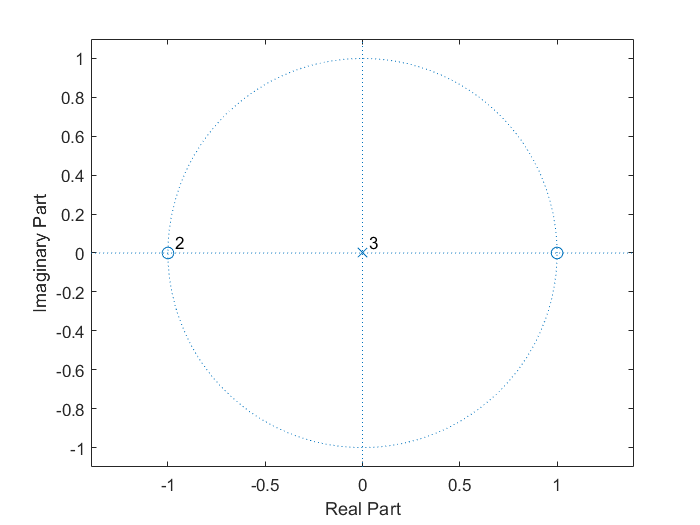

b = [1 1 -1 -1];
b = 0.25.*b;
a = [1];
figure; zplane(b, a);

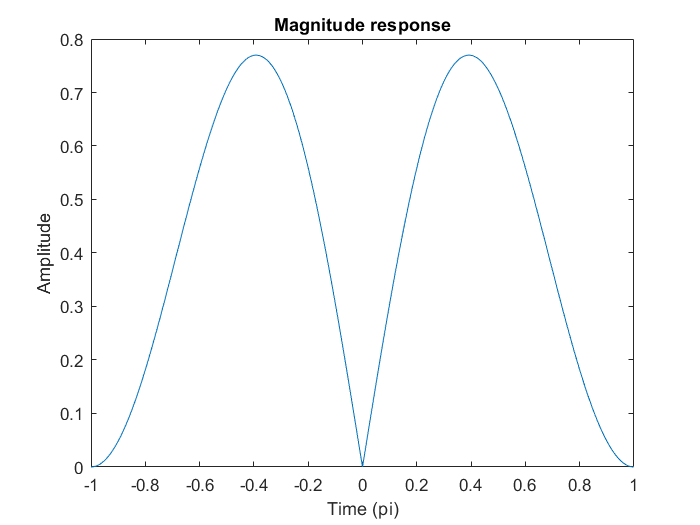

H = freqz(b,a,w);
figure; mag=abs(H); plot(w/pi,mag);
title('Magnitude response');
ylabel('Amplitude');
xlabel('Time (pi)');

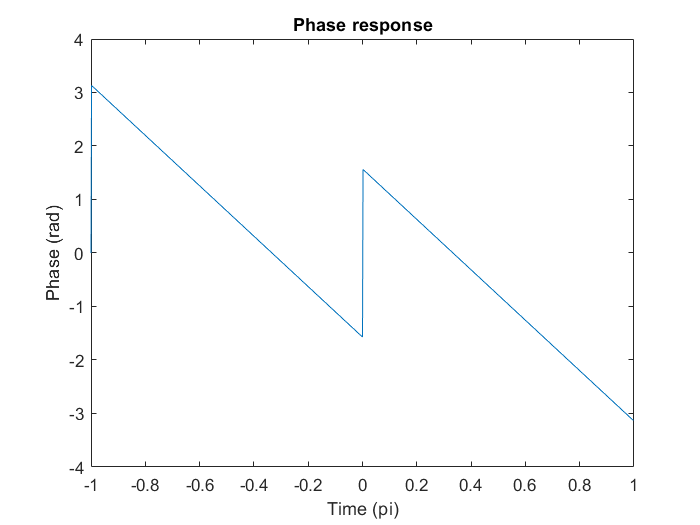

figure; phase=angle(H); plot(w/pi,phase);
title('Phase response');
ylabel('Phase (rad)');
xlabel('Time (pi)');


fprintf('1(b)\n');

1(b)


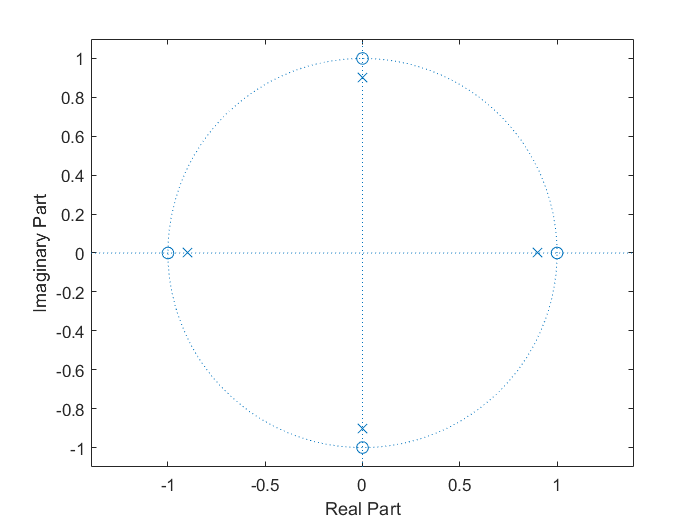

b = [1 0 0 0 -1];
a = [1 0 0 0 -0.6561];
figure; zplane(b, a);

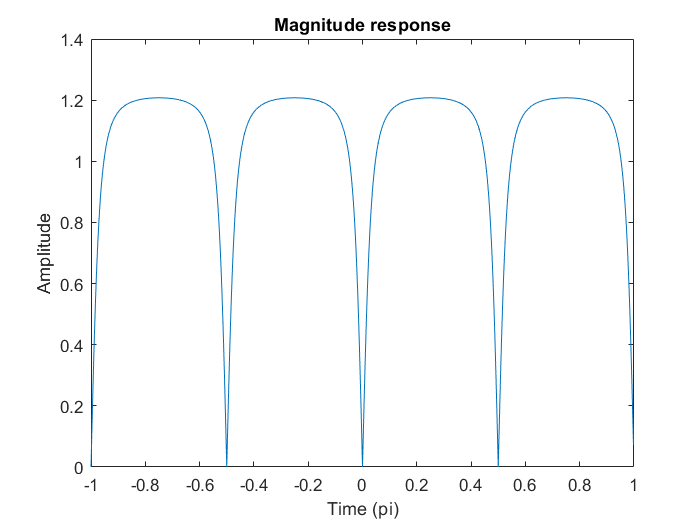

H = freqz(b,a,w);
figure; mag=abs(H); plot(w/pi,mag);
title('Magnitude response');
ylabel('Amplitude');
xlabel('Time (pi)');

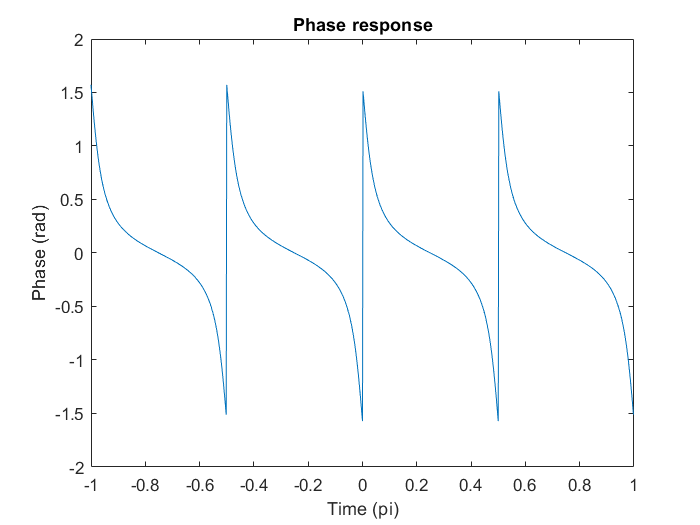

figure; phase=angle(H); plot(w/pi,phase);
title('Phase response');
ylabel('Phase (rad)');
xlabel('Time (pi)');

Hw3-2

close all; clear;

fprintf('2\n');

2


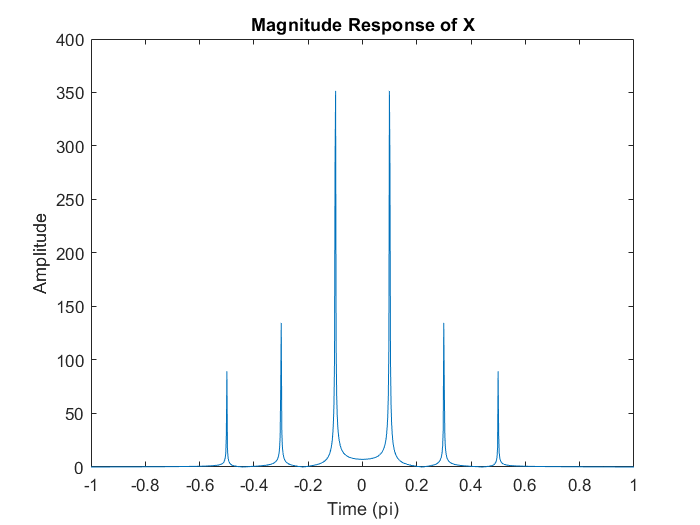

om=linspace(-pi, pi, 1000);
n = linspace(0,1000,1001);
x = sin(0.1*pi*n)+(1/3)*sin(0.3*pi*n)+0.2*sin(0.5*pi*n);
X = freqz(x,1,om);
figure; plot(om/pi, abs(X));
title('Magnitude Response of X');
ylabel('Amplitude');
xlabel('Time (pi)');

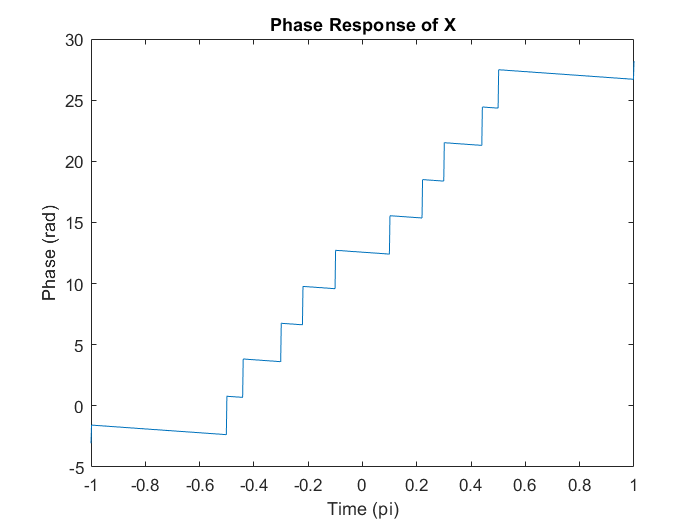

figure; plot(om/pi, unwrap(angle(X)));
title('Phase Response of X');
ylabel('Phase (rad)');
xlabel('Time (pi)');


fprintf('2(a)\n');

2(a)


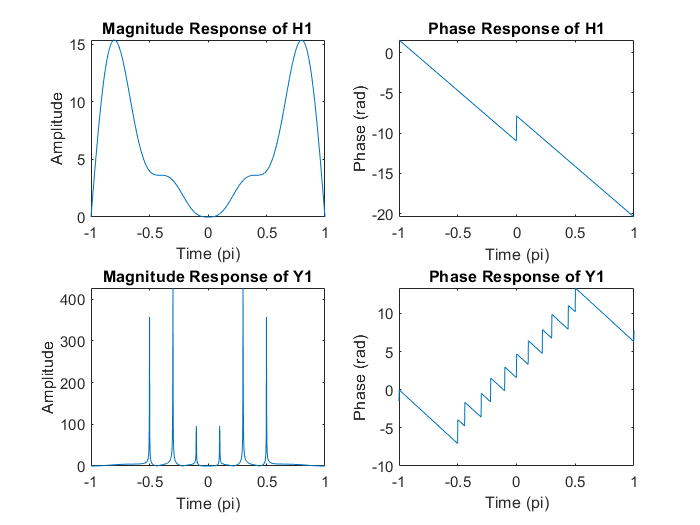

h1 = [1 -2 3 -4 0 4 -3 2 -1]; % start from n=0
H1 = freqz(h1,1,om); H1 = exp(-j*om*0).*H1;
figure; 
subplot(2,2,1); plot(om/pi, abs(H1));
title('Magnitude Response of H1');
ylabel('Amplitude');
xlabel('Time (pi)');
subplot(2,2,2); plot(om/pi, unwrap(angle(H1)));
title('Phase Response of H1');
ylabel('Phase (rad)');
xlabel('Time (pi)');
Y1 = X.*H1;
subplot(2,2,3); plot(om/pi, abs(Y1));
title('Magnitude Response of Y1');
ylabel('Amplitude');
xlabel('Time (pi)');
subplot(2,2,4); plot(om/pi, unwrap(angle(Y1)));
title('Phase Response of Y1');
ylabel('Phase (rad)');
xlabel('Time (pi)');



fprintf('2(b)\n');

2(b)


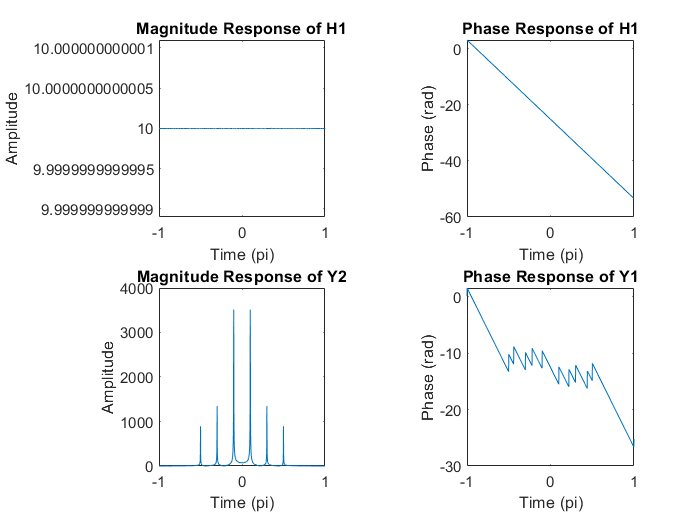

b = zeros(1, 10); b(10) = 10;
a = [1];
H2 = freqz(b,a,om);
figure; 
subplot(2,2,1); plot(om/pi, abs(H2));
title('Magnitude Response of H1');
ylabel('Amplitude');
xlabel('Time (pi)');
subplot(2,2,2); plot(om/pi, unwrap(angle(H2)));
title('Phase Response of H1');
ylabel('Phase (rad)');
xlabel('Time (pi)');
Y2 = X.*H2;
subplot(2,2,3); plot(om/pi, abs(Y2));
title('Magnitude Response of Y2');
ylabel('Amplitude');
xlabel('Time (pi)');
subplot(2,2,4); plot(om/pi, unwrap(angle(Y2)));
title('Phase Response of Y1');
ylabel('Phase (rad)');
xlabel('Time (pi)');

Hw3-3

close all; clear;
fprintf('3\n');

3


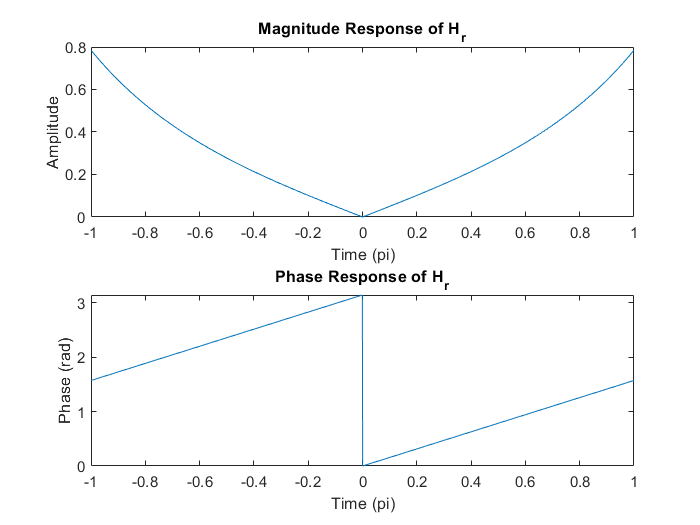

om=linspace(-pi, pi, 2000);

H = (om/(2*pi)).*((om/2)./sin(om/2)).*exp(i.*om/2);
figure; 
subplot(2,1,1); plot(om/pi, abs(H));
title('Magnitude Response of H_r');
ylabel('Amplitude');
xlabel('Time (pi)');
subplot(2,1,2); plot(om/pi, unwrap(angle(H)));
title('Phase Response of H_r');
ylabel('Phase (rad)');
xlabel('Time (pi)');

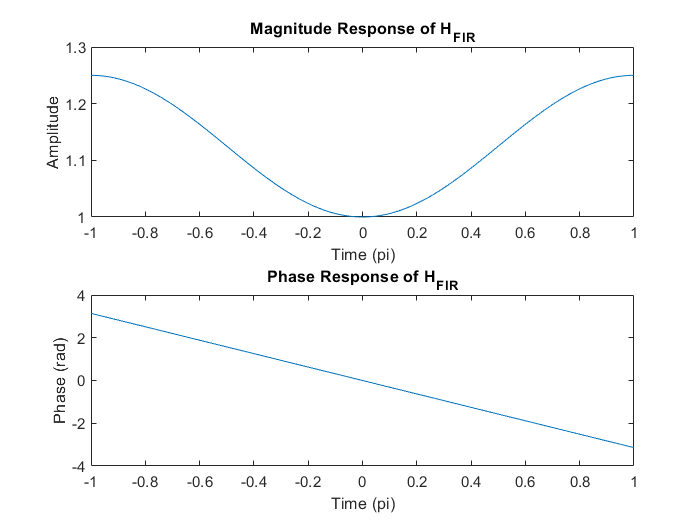


b_FIR = [-1/16 9/8 -1/16]; a_FIR = [1];
b_IIR = [9]; a_IIR = [8 1];

H_FIR = freqz(b_FIR,a_FIR,om);
%figure; zplane(b_FIR,a_FIR);
figure; 
subplot(2,1,1); plot(om/pi, abs(H_FIR));
title('Magnitude Response of H_F_I_R');
ylabel('Amplitude');
xlabel('Time (pi)');
subplot(2,1,2); plot(om/pi, unwrap(angle(H_FIR)));
title('Phase Response of H_F_I_R');
ylabel('Phase (rad)');
xlabel('Time (pi)');

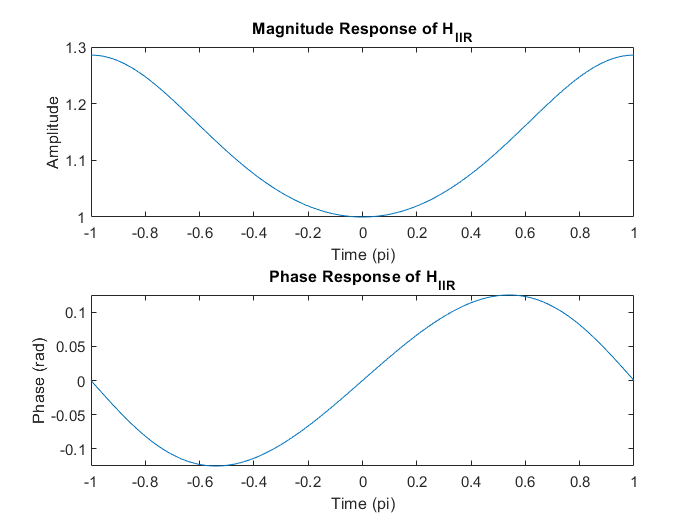


H_IIR = freqz(b_IIR,a_IIR,om);
%figure; zplane(b_IIR,a_IIR);
figure; 
subplot(2,1,1); plot(om/pi, abs(H_IIR));
title('Magnitude Response of H_I_I_R');
ylabel('Amplitude');
xlabel('Time (pi)');
subplot(2,1,2); plot(om/pi, unwrap(angle(H_IIR)));
title('Phase Response of H_I_I_R');
ylabel('Phase (rad)');
xlabel('Time (pi)');

Hw3-4

close all; clear;
fprintf('4\n');

4


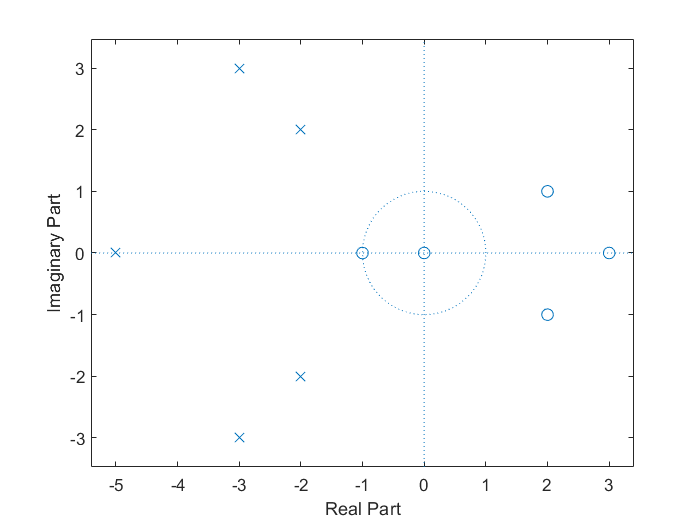

om = linspace(-pi, pi, 1000);
n = linspace(0,1000,1001);

b = [1 -6 10 2 -15]; a = [1 15 100 370 744 720];
figure; zplane(b, a);

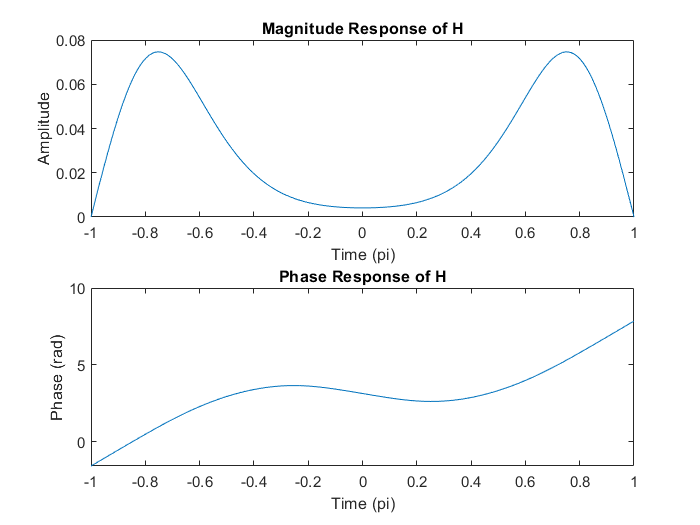

H = freqz(b,a,om);
figure; 
subplot(2,1,1); plot(om/pi, abs(H));
title('Magnitude Response of H');
ylabel('Amplitude');
xlabel('Time (pi)');
subplot(2,1,2); plot(om/pi, unwrap(angle(H)));
title('Phase Response of H');
ylabel('Phase (rad)');
xlabel('Time (pi)');

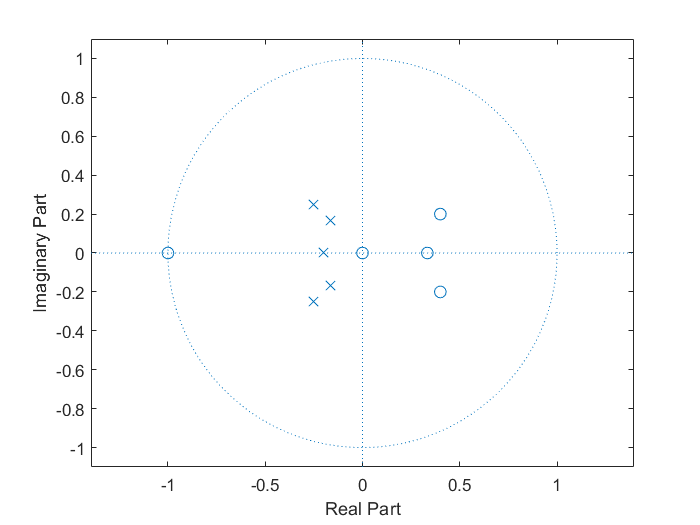


min_b1 = [1  1]; min_b2 = [-3 1]; min_b3 = [5 -4 1];
min_a1 = [5 1]; min_a2 = [8 4 1]; min_a3 = [18 6 1];
min_b = conv(min_b1,min_b2); min_b = conv(min_b, min_b3);
min_a = conv(min_a1,min_a2); min_a = conv(min_a, min_a3);

ap_b1 = [1 -3]; ap_b2 = [1 -4 5]; ap_b3 = [5 1]; ap_b4 = [8 4 1]; ap_b5 = [18 6 1];
ap_a1 = [1 5]; ap_a2 = [1 4 8]; ap_a3 = [1 6 18]; ap_a4 = [-3 1]; ap_a5 = [5 -4 1];
ap_b = conv(ap_b1, ap_b2); ap_b = conv(ap_b, ap_b3); ap_bt = conv(ap_b4, ap_b5); ap_b = conv(ap_b,ap_bt);
ap_a = conv(ap_a1, ap_a2); ap_a = conv(ap_a, ap_a3); ap_at = conv(ap_a4, ap_a5); ap_a = conv(ap_a,ap_at);

H_min = freqz(min_b,min_a,om);
figure; zplane(min_b, min_a);

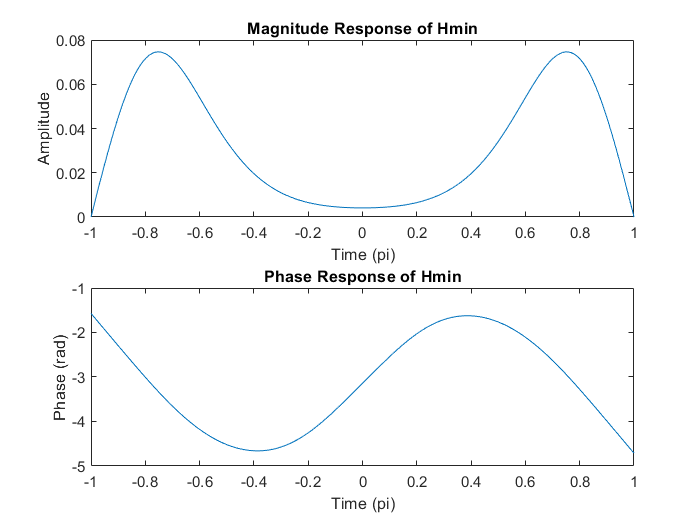

figure; 
subplot(2,1,1); plot(om/pi, abs(H_min));
title('Magnitude Response of Hmin');
ylabel('Amplitude');
xlabel('Time (pi)');
subplot(2,1,2); plot(om/pi, unwrap(angle(H_min)));
title('Phase Response of Hmin');
ylabel('Phase (rad)');
xlabel('Time (pi)');

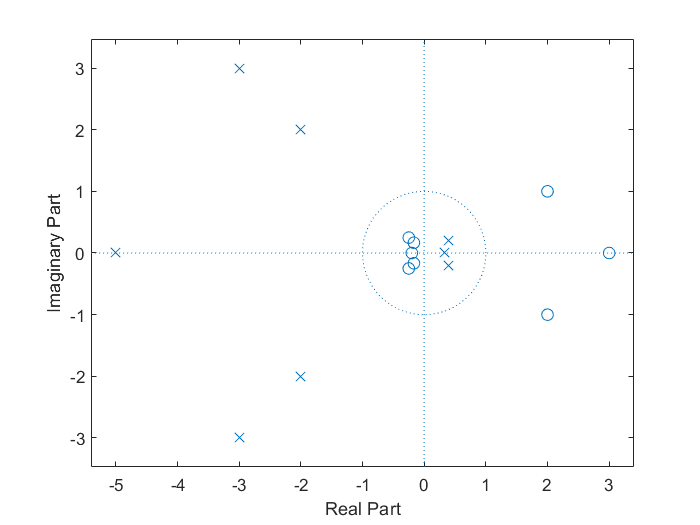


H_ap = freqz(ap_b,ap_a,om);
figure; zplane(ap_b, ap_a);

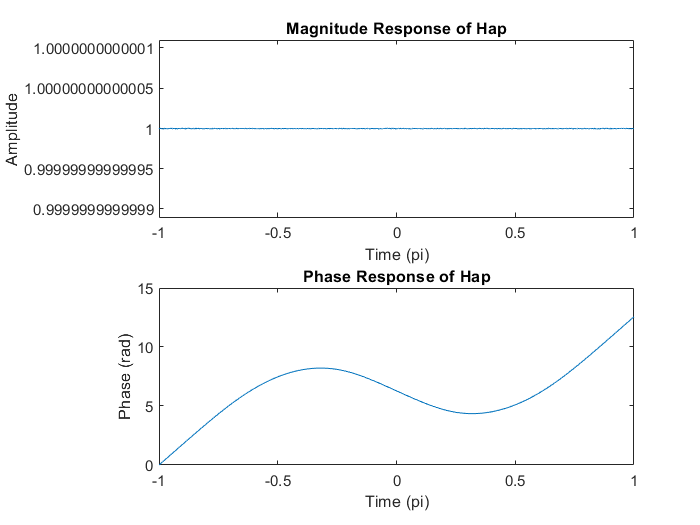

figure; 
subplot(2,1,1); plot(om/pi, abs(H_ap));
title('Magnitude Response of Hap');
ylabel('Amplitude');
xlabel('Time (pi)');
subplot(2,1,2); plot(om/pi, unwrap(angle(H_ap)));
title('Phase Response of Hap');
ylabel('Phase (rad)');
xlabel('Time (pi)');

Hw3-5

close all; clear;
fprintf('5\n');

5


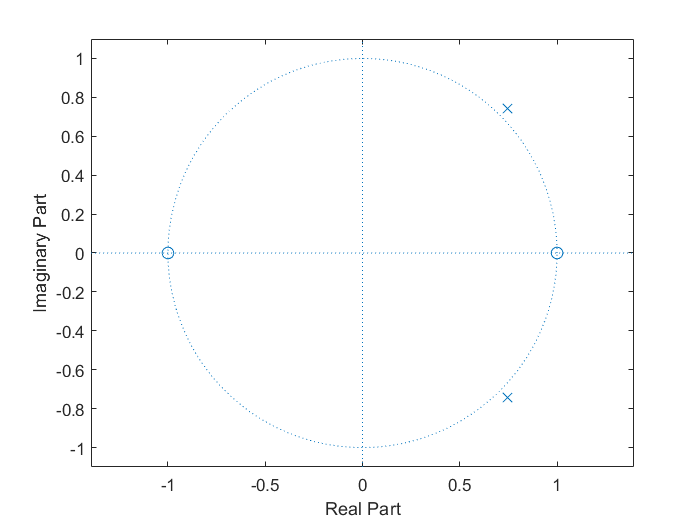

om = linspace(-pi, pi, 1000);

b = [1 0 -1]; a = [18 -26.82 19.98];
figure; zplane(b, a);

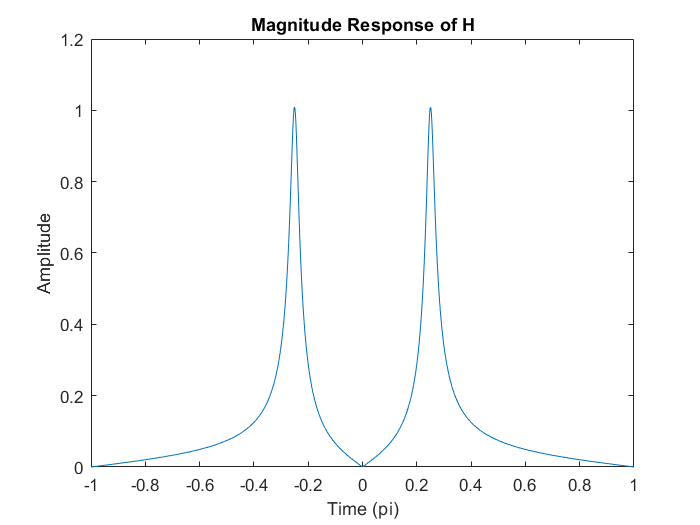

[H, w] = freqz(b,a,om);

% figure; 
% subplot(2,1,1); plot(om/pi, abs(H));
% title('Magnitude Response of H');
% ylabel('Amplitude');
% xlabel('Time (pi)');
% subplot(2,1,2); plot(om/pi, unwrap(angle(H)));
% title('Phase Response of H');
% ylabel('Phase (rad)');
% xlabel('Time (pi)');

figure; plot(om/pi, abs(H));
title('Magnitude Response of H');
ylabel('Amplitude');
xlabel('Time (pi)');

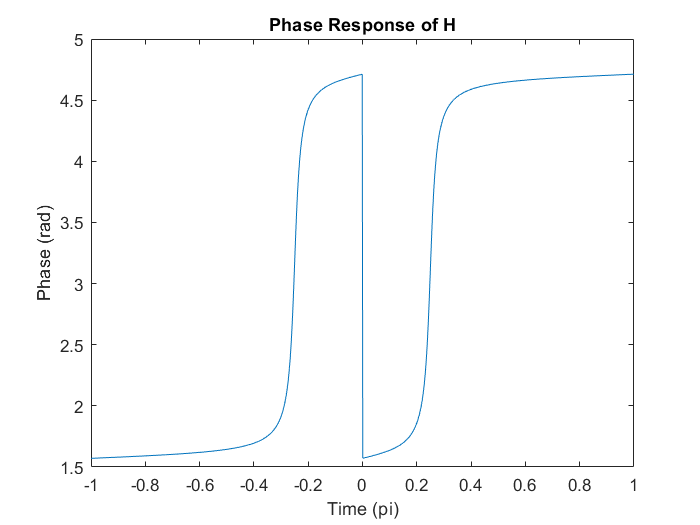

figure; plot(om/pi, unwrap(angle(H)));
title('Phase Response of H');
ylabel('Phase (rad)');
xlabel('Time (pi)');

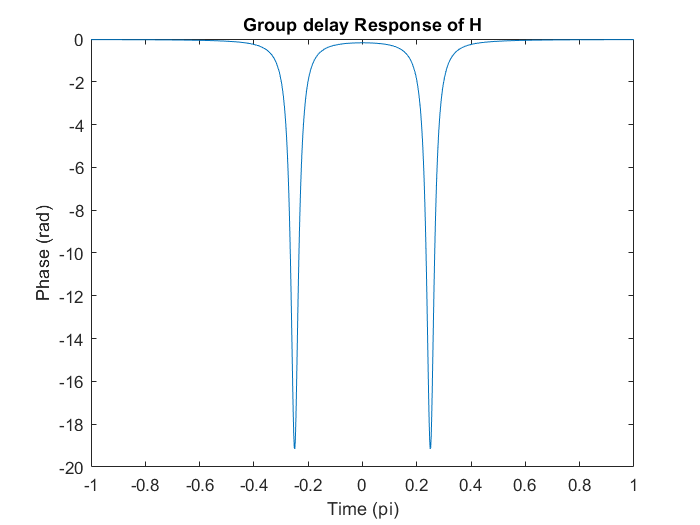


gd = grpdelay(b,a,om);

figure; plot(om/pi, gd);
title('Group delay Response of H')
ylabel('Phase (rad)');
xlabel('Time (pi)');

Hw3-6

close all; clear;
fprintf('6\n');

6


om = linspace(-pi, pi, 1000);

t = 8000;

fprintf('6(a)\n');

6(a)


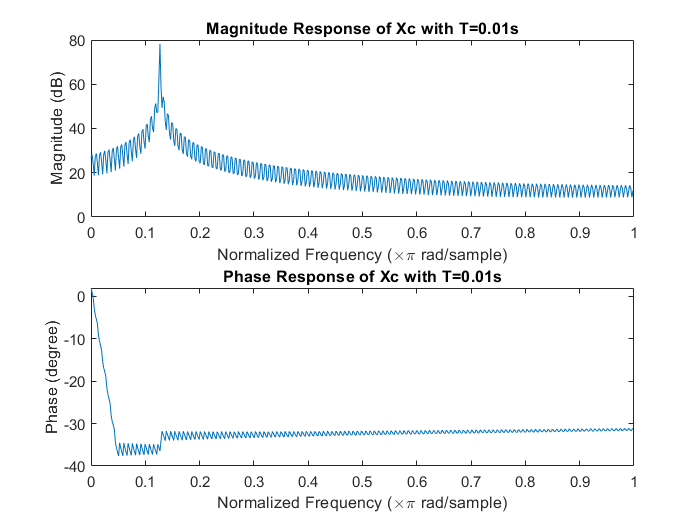

T1 = 0.01; T2 = 0.04; T3 = 0.1;

om1 = linspace(0, t, t/T1);
x11 = 5*exp(i*40*om1) + 3*exp(-70*i*om1);
[h11, w11] = freqz(x11, 1);
figure; 
subplot(2,1,1); plot(w11/pi, 20*log10(abs(h11)));
title('Magnitude Response of Xc with T=0.01s');
ylabel('Magnitude (dB)');
xlabel('Normalized Frequency (\times\pi rad/sample)');
subplot(2,1,2); plot(w11/pi, unwrap(angle(h11)));
title('Phase Response of Xc with T=0.01s');
ylabel('Phase (degree)');
xlabel('Normalized Frequency (\times\pi rad/sample)');

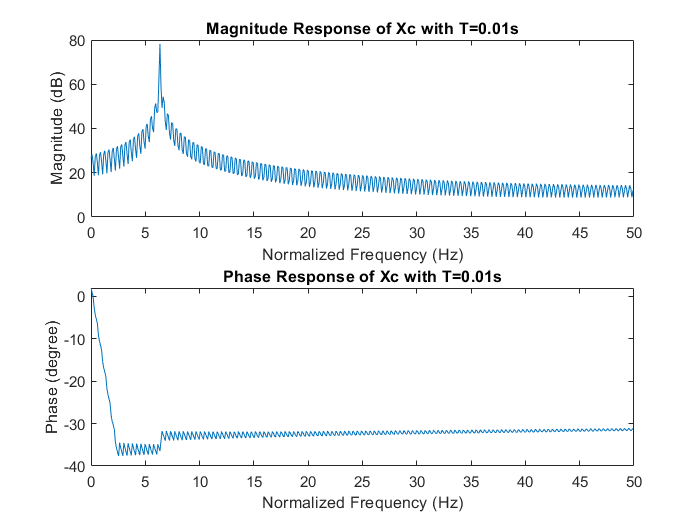

figure; 
subplot(2,1,1); plot(w11/(2*pi*T1), 20*log10(abs(h11)));
title('Magnitude Response of Xc with T=0.01s');
ylabel('Magnitude (dB)');
xlabel('Normalized Frequency (Hz)');
subplot(2,1,2); plot(w11/(2*pi*T1), unwrap(angle(h11)));
title('Phase Response of Xc with T=0.01s');
ylabel('Phase (degree)');
xlabel('Normalized Frequency (Hz)');

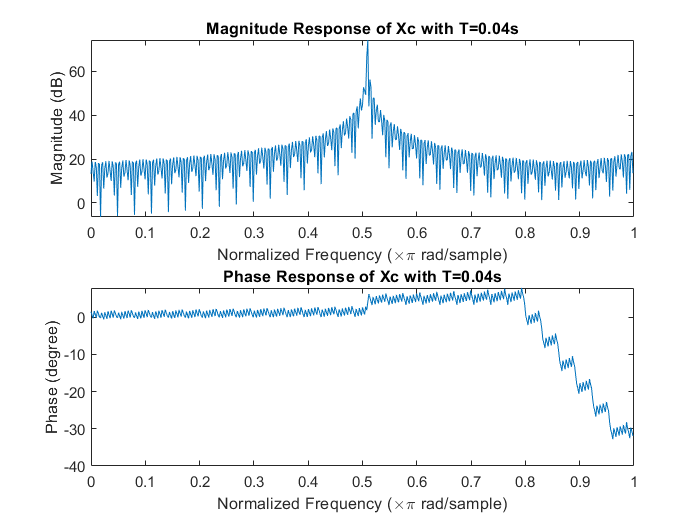


om1 = linspace(0, t, t/T2);
x12 = 5*exp(i*40*om1) + 3*exp(-70*i*om1);
[h12, w12] = freqz(x12, 1);
figure; 
subplot(2,1,1); plot(w12/pi, 20*log10(abs(h12)));
title('Magnitude Response of Xc with T=0.04s');
ylabel('Magnitude (dB)');
xlabel('Normalized Frequency (\times\pi rad/sample)');
subplot(2,1,2); plot(w12/pi, unwrap(angle(h12)));
title('Phase Response of Xc with T=0.04s');
ylabel('Phase (degree)');
xlabel('Normalized Frequency (\times\pi rad/sample)');

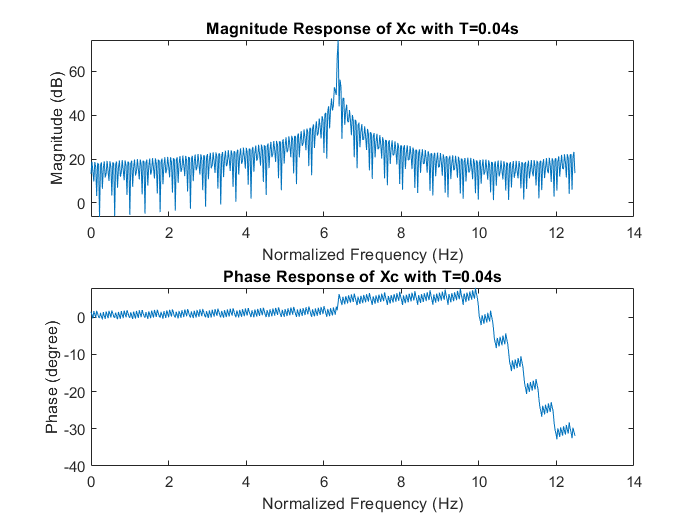

figure; 
subplot(2,1,1); plot((w12/(2*pi*T2)), 20*log10(abs(h12)));
title('Magnitude Response of Xc with T=0.04s');
ylabel('Magnitude (dB)');
xlabel('Normalized Frequency (Hz)');
subplot(2,1,2); plot((w12/(2*pi*T2)), unwrap(angle(h12)));
title('Phase Response of Xc with T=0.04s');
ylabel('Phase (degree)');
xlabel('Normalized Frequency (Hz)');

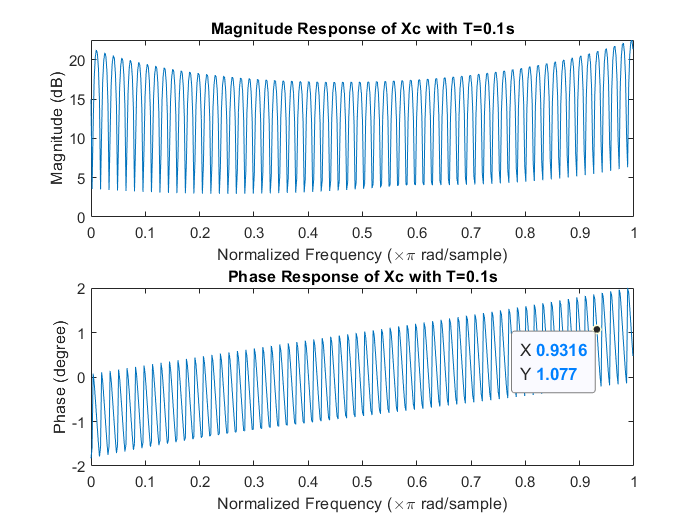


om1 = linspace(0, t, t/T3);
x13 = 5*exp(i*40*om1) + 3*exp(-70*i*om1);
[h13, w13] = freqz(x13, 1);
figure; 
subplot(2,1,1); plot(w13/pi, 20*log10(abs(h13)));
title('Magnitude Response of Xc with T=0.1s');
ylabel('Magnitude (dB)');
xlabel('Normalized Frequency (\times\pi rad/sample)');
subplot(2,1,2); plot(w13/pi, unwrap(angle(h13)));
title('Phase Response of Xc with T=0.1s');
ylabel('Phase (degree)');
xlabel('Normalized Frequency (\times\pi rad/sample)');

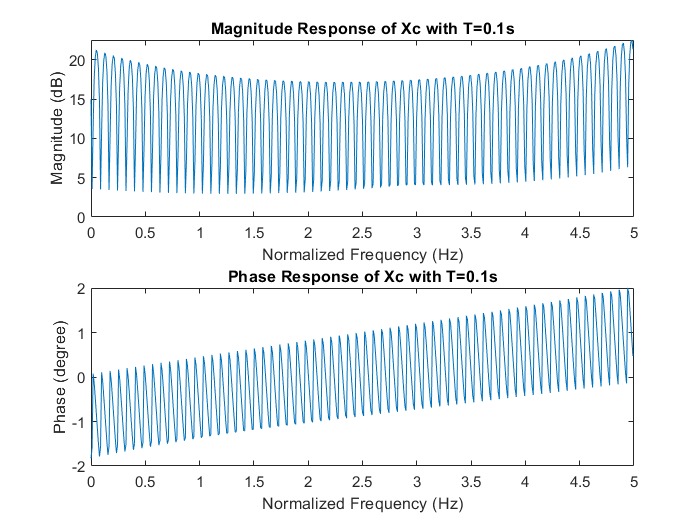

figure; 
subplot(2,1,1); plot(w13/(2*pi*T3), 20*log10(abs(h13)));
title('Magnitude Response of Xc with T=0.1s');
ylabel('Magnitude (dB)');
xlabel('Normalized Frequency (Hz)');
subplot(2,1,2); plot(w13/(2*pi*T3), unwrap(angle(h13)));
title('Phase Response of Xc with T=0.1s');
ylabel('Phase (degree)');
xlabel('Normalized Frequency (Hz)');


fprintf('6(b)\n');

6(b)


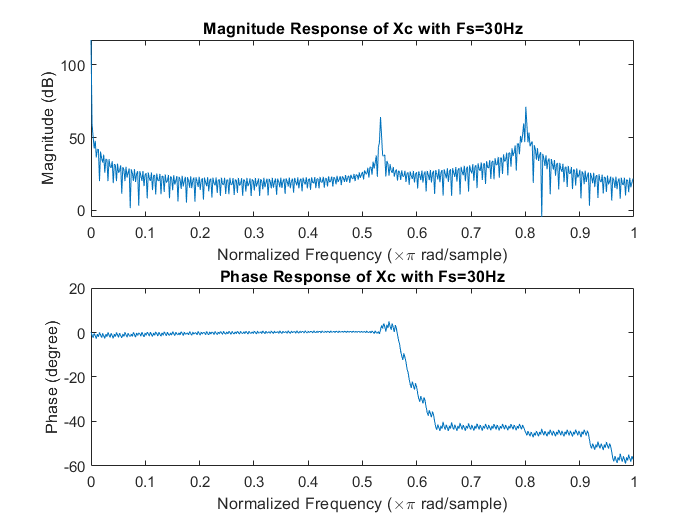

Fs1 = 30; Fs2 = 20; Fs3 = 15;

om2 = linspace(0, t, Fs1*t);
x21 = 3 + 2*sin(16*pi*om2) + 10*cos(24*pi*om2);
[h21, w21] = freqz(x21, 1);
figure; 
subplot(2,1,1); plot(w21/pi, 20*log10(abs(h21)));
title('Magnitude Response of Xc with Fs=30Hz');
ylabel('Magnitude (dB)');
xlabel('Normalized Frequency (\times\pi rad/sample)');
subplot(2,1,2); plot(w21/pi, unwrap(angle(h21)));
title('Phase Response of Xc with Fs=30Hz');
ylabel('Phase (degree)');
xlabel('Normalized Frequency (\times\pi rad/sample)');

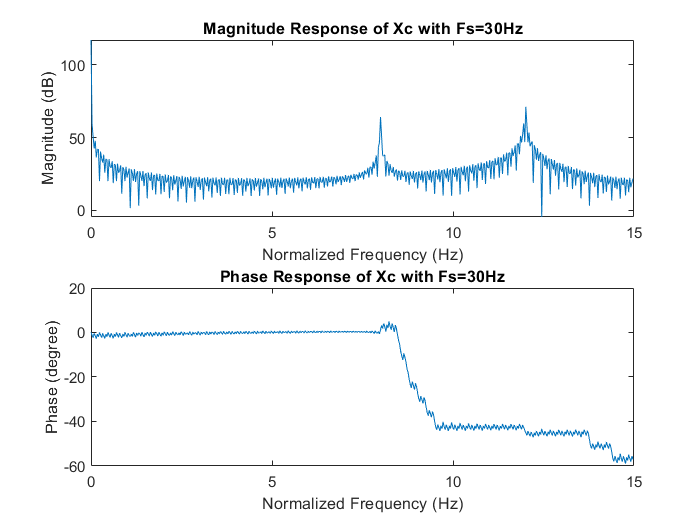

figure; 
subplot(2,1,1); plot(w21*Fs1/(2*pi), 20*log10(abs(h21)));
title('Magnitude Response of Xc with Fs=30Hz');
ylabel('Magnitude (dB)');
xlabel('Normalized Frequency (Hz)');
subplot(2,1,2); plot(w21*Fs1/(2*pi), unwrap(angle(h21)));
title('Phase Response of Xc with Fs=30Hz');
ylabel('Phase (degree)');
xlabel('Normalized Frequency (Hz)');

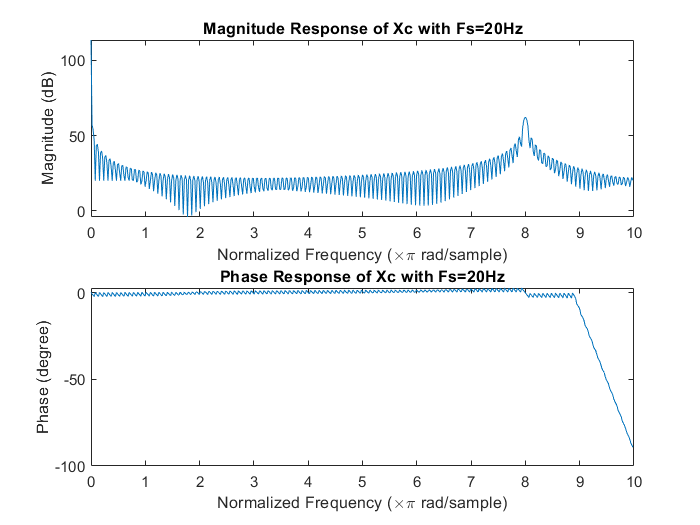


om2 = linspace(0, t, Fs2*t);
x22 = 3 + 2*sin(16*pi*om2) + 10*cos(24*pi*om2);
[h22, w22] = freqz(x22, 1);
figure; 
subplot(2,1,1); plot(w22*Fs2/(2*pi), 20*log10(abs(h22)));
title('Magnitude Response of Xc with Fs=20Hz');
ylabel('Magnitude (dB)');
xlabel('Normalized Frequency (\times\pi rad/sample)');
subplot(2,1,2); plot(w22*Fs2/(2*pi), unwrap(angle(h22)));
title('Phase Response of Xc with Fs=20Hz');
ylabel('Phase (degree)');
xlabel('Normalized Frequency (\times\pi rad/sample)');

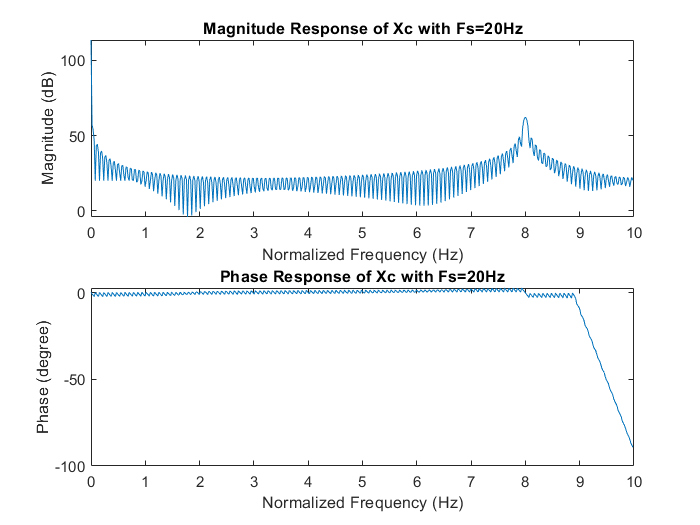

figure; 
subplot(2,1,1); plot(w22*Fs2/(2*pi), 20*log10(abs(h22)));
title('Magnitude Response of Xc with Fs=20Hz');
ylabel('Magnitude (dB)');
xlabel('Normalized Frequency (Hz)');
subplot(2,1,2); plot(w22*Fs2/(2*pi), unwrap(angle(h22)));
title('Phase Response of Xc with Fs=20Hz');
ylabel('Phase (degree)');
xlabel('Normalized Frequency (Hz)');

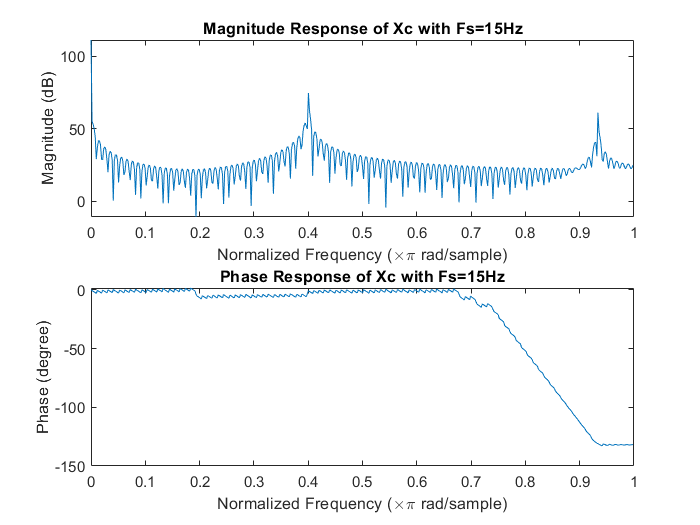


om2 = linspace(0, t, Fs3*t);
x23 = 3 + 2*sin(16*pi*om2) + 10*cos(24*pi*om2); 
[h23, w23] = freqz(x23, 1);
figure; 
subplot(2,1,1); plot(w23/pi, 20*log10(abs(h23)));
title('Magnitude Response of Xc with Fs=15Hz');
ylabel('Magnitude (dB)');
xlabel('Normalized Frequency (\times\pi rad/sample)');
subplot(2,1,2); plot(w23/pi, unwrap(angle(h23)));
title('Phase Response of Xc with Fs=15Hz');
ylabel('Phase (degree)');
xlabel('Normalized Frequency (\times\pi rad/sample)');

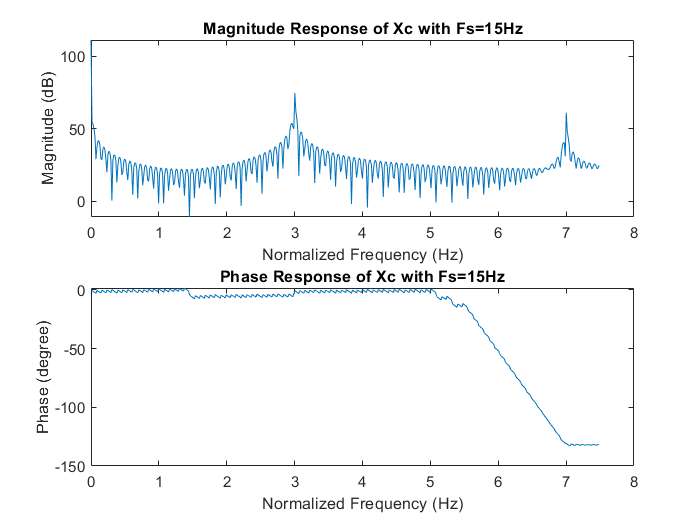

figure; 
subplot(2,1,1); plot(w23*Fs3/(2*pi), 20*log10(abs(h23)));
title('Magnitude Response of Xc with Fs=15Hz');
ylabel('Magnitude (dB)');
xlabel('Normalized Frequency (Hz)');
subplot(2,1,2); plot(w23*Fs3/(2*pi), unwrap(angle(h23)));
title('Phase Response of Xc with Fs=15Hz');
ylabel('Phase (degree)');
xlabel('Normalized Frequency (Hz)');


% subplot(3,1,1); plot(w21*Fs1/(2*pi), 20*log10(abs(h21)));
% title('Magnitude Response of Xc with Fs=30Hz');
% ylabel('Magnitude (dB)');
% xlabel('Normalized Frequency (Hz)');
% subplot(3,1,2); plot(w22*Fs2/(2*pi), 20*log10(abs(h22)));
% title('Magnitude Response of Xc with Fs=20Hz');
% ylabel('Magnitude (dB)');
% xlabel('Normalized Frequency (Hz)');
% subplot(3,1,3); plot(w23*Fs3/(2*pi), 20*log10(abs(h23)));
% title('Magnitude Response of Xc with Fs=15Hz');
% ylabel('Magnitude (dB)');
% xlabel('Normalized Frequency (Hz)');